# 3D Voronoi Network

% Copyright (c) 2020 Shiyu Liu. All rights reserved.

clc
clear
close all

filename='Voronoi3D_20200607T000000.mat';
load(filename)

## Visualization of 3D Voronoi Cuboid

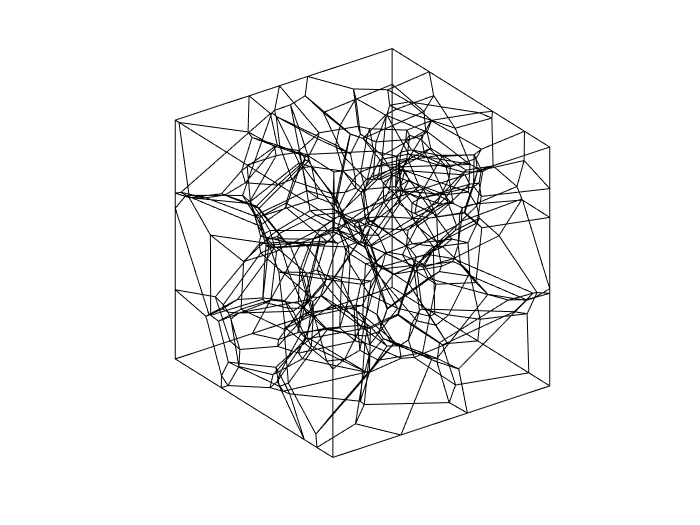

h=figure;
ax = axes('Parent',h);
ax.XAxis.Visible = 'off';
ax.YAxis.Visible = 'off';
ax.ZAxis.Visible = 'off';

hold on
axis('equal')
view([-36 27])
% scatter3(seeds(:,1),seeds(:,2),seeds(:,3),25, ...
%     'Marker','o','MarkerFaceColor',[1 0 0], 'MarkerEdgeColor','k');
% scatter3(Ver(:,1),Ver(:,2),Ver(:,3),25, ...
%     'Marker','o','MarkerFaceColor',[0 1 0], 'MarkerEdgeColor','r');

for k = 1:length(Cel)
    if ~isempty(Cel{k})
        col=rand(1,3);
        Vk = Ver(Cel{k},:); Fk = convhull(Vk);
        if exist('mergeCoplanarFaces.m','file')==2
            [Vk, Fk] = mergeCoplanarFaces(Vk, Fk);
            for i=1:length(Fk)
                patch('Vertices',Vk,'Faces',Fk{i},'FaceColor',col,'FaceAlpha',0)
            end
        else
            trisurf(Fk,Vk(:,1),Vk(:,2),Vk(:,3),'FaceColor',col, ...
                'FaceAlpha', 1,'EdgeAlpha',1,'EdgeColor','k')
        end
    end
end
xlabel('X');ylabel('Y');zlabel('Z');